data = load('resultadosCSV_2M.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

load('DatosCalibracion.mat');
T           = 5e-9;

T_buscado = 1/(2*2e6)

T_buscado =      2.500000000000000e-07


T_buscado/50

ans =      5.000000000000000e-09


#### Separación de datos

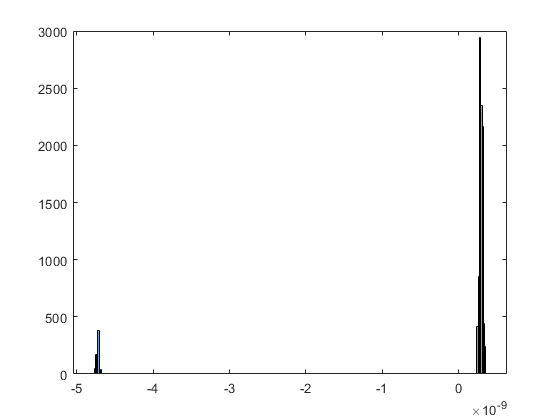

t_fino = (start)*tau_start - (stop)*tau_stop;
histogram(t_fino, 300)

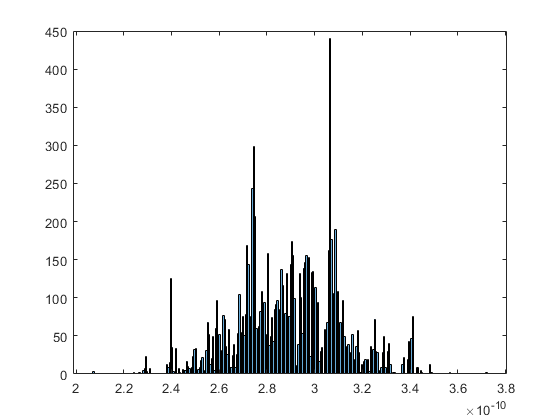

histogram([t_fino(t_fino>0); t_fino(t_fino<0)+T], 300)

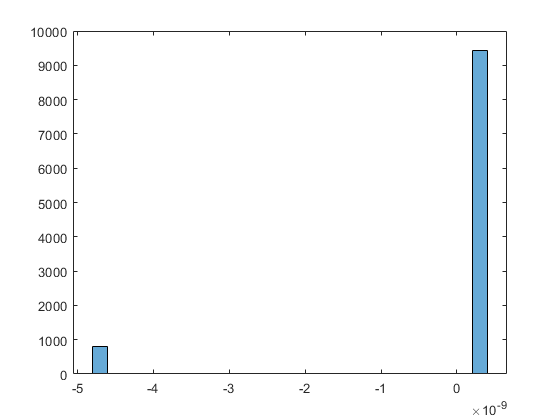

% t_fino = (start-stop)*tau_stop;
t = (coarse*T) + t_fino;
histogram(t_fino)   

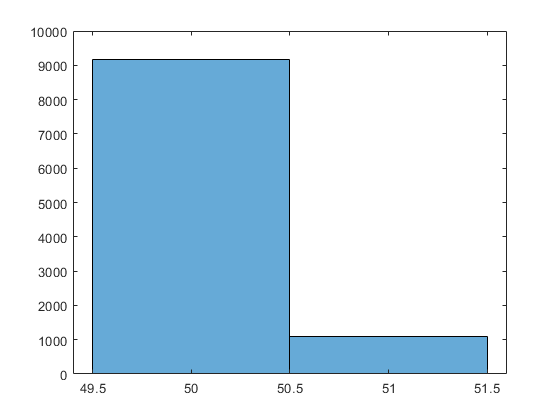

histogram(coarse)

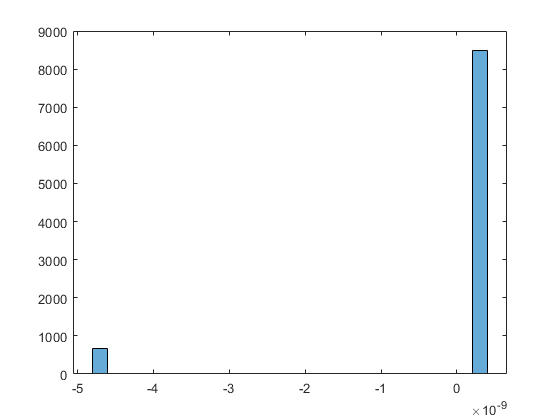

sprintf('50 coarse son: %d y lo buscado es: %d', 50*T, T_buscado);
indices_50 = find(coarse==50);
indices_51 = find(coarse==51);

%Mediciones 50
clf;

fino_50 = t_fino(indices_50);
start_50 = start(indices_50);
stop_50 = stop(indices_50);
coarse_50 = coarse(indices_50);
histogram(fino_50)

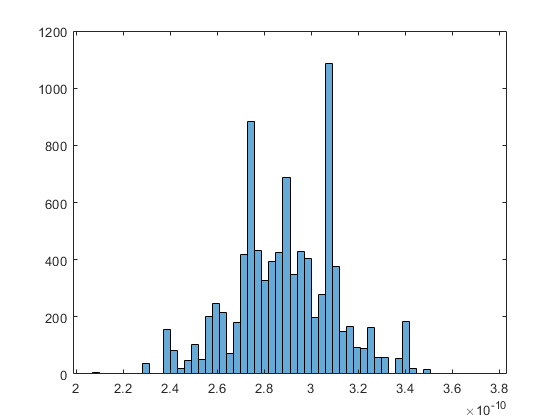

fino_50_buenas = fino_50(fino_50>0);
fino_50_malas  = fino_50(fino_50<0);
start_50_buenos = start_50(fino_50>0);
stop_50_buenos  = stop_50(fino_50>0);
start_50_malos = start_50(fino_50<0);
stop_50_malos  = stop_50(fino_50<0);
histogram([fino_50_buenas; fino_50_malas+T])

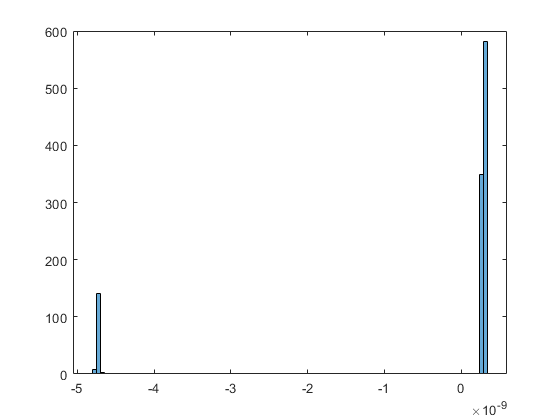


%%Mediciones 51
clf;
fino_51 = t_fino(indices_51);
coarse_51 = coarse(indices_51);
histogram(fino_51, 100)

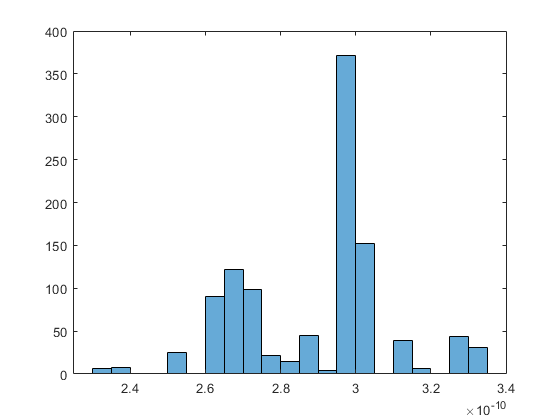

fino_51_buenas = fino_51(fino_51<0);
fino_51_malas = fino_51(fino_51>0);
histogram([fino_51_buenas+T; fino_51_malas])

st = start-stop

st =     18
    18
    16
    16
    18
    16
    18
    16
    16
    16


indices_st_pos = find(st>0);
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (maxbin_start-minbin_start);
length(st)

ans =        10240


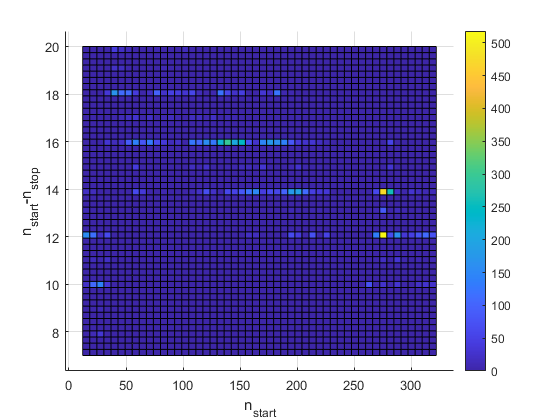

hist3([start, st], 'CdataMode','auto', 'Nbins', [50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_2M.eps');

tiempos_finos = cal_start(start)-cal_stop(stop)

tiempos_finos = 	1.0e+-8 *

   0.039746093750000   0.039746093750000   0.036181640625000   0.036181640625000   0.038818359375000   0.035498046875000   0.038818359375000   0.035498046875000   0.035498046875000   0.035498046875000   0.038818359375000   0.038818359375000   0.036181640625000   0.038818359375000   0.038818359375000   0.035498046875000   0.035498046875000   0.035498046875000   0.035498046875000   0.035498046875000   0.035498046875000   0.036181640625000   0.035498046875000   0.035498046875000   0.035498046875000   0.038818359375000   0.035498046875000   0.035498046875000   0.035498046875000   0.035498046875000   0.035498046875000   0.035498046875000   0.038964843750000   0.038964843750000   0.035498046875000   0.035498046875000   0.035498046875000   0.035498046875000   0.038964843750000   0.035498046875000   0.035498046875000   0.035498046875000   0.038964843750000   0.038964843750000   0.035498046875000   0.038964843750000   0.035498046875000   0.038818359375000   0.0388183

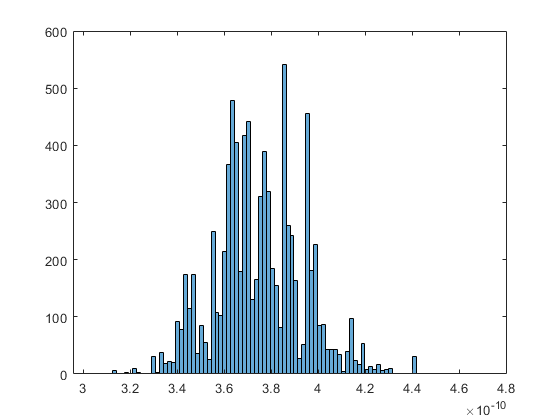

histogram(tiempos, 100);

mean(tiempos)

ans =      3.751433636509115e-10


std(tiempos)

ans =      1.895488742055021e-11


#### Export

clf;
y = [fino_50_malas+T; fino_50_buenas; fino_51];
presicion = std(y)

presicion =      6.004785931480944e-10


media     = mean(y)

media =      2.165938066238764e-10


coarse_correcto = 50;
N = 100;
% Clear figure
clf;

% Data vectors
data = {fino_51, fino_50_malas+T, fino_50_buenas};

% Number of bins
N = 100;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = linspace(min_val, max_val, N+1);

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end
length(fino_51)

ans =         1080


length(fino_50_malas)

ans =    664


length(fino_50_buenas)

ans =         8496


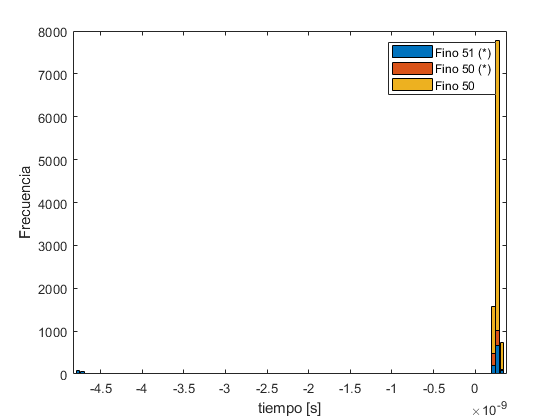

% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo [s]');
ylabel('Frecuencia');
legend({['Fino 51 (*)'], 'Fino 50 (*)', 'Fino 50'});
exportgraphics(gcf,'histograma_2M.eps');




format long
T_buscado

T_buscado =      2.500000000000000e-07


Tiempo_final = 50*T + media

Tiempo_final =      2.502165938066239e-07


error = Tiempo_final - T_buscado

error =      2.165938066238778e-10


clf;
% Clear figure
clf;

% Data vectors
data = {coarse_51, coarse_50_malas, coarse_50_buenas};

Unrecognized function or variable 'coarse_50_malas'.


% Number of bins
N = 8;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = 49.5:0.25:51.5

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end

bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('Grueso');
ylabel('Frecuencia');
legend({['Grueso 51 (*)'], 'Grueso 50 (*)', 'Grueso 50'});
exportgraphics(gcf,'histograma_coarse_2M.eps');

% clear;
% data = load('resultadosCSV_2m_7.txt');
% 
% stop    = data(:, 1);
% start   = data(:, 2);
% coarse  = data(:, 3);
% 
% tau_stop    = 15.72e-12;
% n_min_stop  = 35;
% n_max_stop  = 353;
% tau_start   = 16.23e-12;
% n_min_start = 27
% n_max_start = 335
% T           = 5e-9;
% 
% T_buscado = 1/(2*2e6)

% t_fino = (start)*tau_start - (stop)*tau_stop;
% t = (coarse*T) + t_fino;
% histogram(t_fino)
% histogram(coarse)
% 
% sprintf('50 coarse son: %d y lo buscado es: %d', 50*T, T_buscado)
% indices_50 = find(coarse==50);
% indices_51 = find(coarse==51);
% 
% x = 1:1:1024
% plot(x, start);
% hold on;
% plot(x, stop);
% plot(x, 50*(coarse-50)+200)
% hold off;
% 
% 50*T
% %Mediciones 50
% clf;
% fino_50 = t_fino(indices_50);
% fino_50_buenas = fino_50(fino_50>0);
% histogram(fino_50_buenas);